# Exam 2023

## Problem 1

% Q1.1
syms theta
R_x(theta) = [1 0 0;
              0 cos(theta) -sin(theta);
              0 sin(theta) cos(theta)];
R_y(theta) = [cos(theta) 0 sin(theta);
              0 1 0;
              -sin(theta) 0 cos(theta)];
R_z(theta) = [cos(theta) -sin(theta) 0;
              sin(theta) cos(theta) 0;
              0 0 1];
R_x = [R_x,[0;0;0];0 0 0 1];
R_y = [R_y,[0;0;0];0 0 0 1];
R_z = [R_z,[0;0;0];0 0 0 1];

angle1 = deg2rad(10);
angle2 = deg2rad(20);
trans3 = 30;
angle4 = deg2rad(40);

T_x = [eye(3),[trans3;0;0];0 0 0 1]

T_x =      1     0     0    30
     0     1     0     0
     0     0     1     0
     0     0     0     1


H = R_y(angle4)*R_y(angle1)*R_z(angle2)*T_x;
vpa(H,4)

$$ans = \left(\begin{array}{cccc} 0.604 & -0.2198 & 0.766 & 18.12\\ 0.342 & 0.9397 & 0 & 10.26\\ -0.7198 & 0.262 & 0.6428 & -21.6\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

% Q1.3
syms a b c d e
x = [0; 1; 0];
y = [-1; 0; 0];
z = [0; 0; 1];
t = [c+e; 0; a-d];
H_24 = [x,y,z,t; 0 0 0 1]

$$H\_24 = \left(\begin{array}{cccc} 0 & -1 & 0 & c+e\\ 1 & 0 & 0 & 0\\ 0 & 0 & 1 & a-d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Problem 2

clear;

syms DH(th,d,a,alpha)
DH(th,d,a,alpha) = [cos(th) -sin(th)*cos(alpha) sin(th)*sin(alpha) a*cos(th);
                    sin(th) cos(th)*cos(alpha) -cos(th)*sin(alpha) a*sin(th);
                    0 sin(alpha) cos(alpha) d;
                    0 0 0 1];

% Q2.2
% Joint i: [theta d a alpha]
% Joint 1: [0 180 80 90]
% Joint 2: [80 0 180 0]
% Joint 3: [30 0 0 90]
% Joint 4: [180 180 0 90]

% Q2.3
syms theta_1 theta_2 d_2
T_02 = [cos(theta_1) 0 sin(theta_1) d_2*sin(theta_1)+90*cos(theta_1);
        sin(theta_1) 0 -cos(theta_1) -d_2*cos(theta_1)+90*sin(theta_1);
        0 1 0 0;
        0 0 0 1];
o2 = [76.1; 87.4; 0];

eqns = [T_02(1,4) == o2(1);
        T_02(2,4) == o2(2)];
S = solve(eqns,[theta_1 d_2])

S = struct with fields:
    theta_1: [2×1 sym]
        d_2: [2×1 sym]


% theta_1 = 1.54rad, d_2 = 73.0 mm
disp(vpa([S.theta_1 S.d_2],5))

$$\left(\begin{array}{cc} 0.17288 & -73.007\\ 1.5359 & 73.007 \end{array}\right)$$

rad2deg(1.5359)

ans = 88.0006

% X1 = 8, Y1 = 8
% X2 = 7, Y2 = 3

## Problem 3

% Q3.1
J = [-0.3 0.96;
     0.4 -0.28;
     0 0;
     0 0;
     0 0;
     1 0];
syms q1_dot q2_dot
q_dot = [q1_dot; q2_dot];
zeta = J*q_dot;

qd_1 = vpa(subs(zeta,[q1_dot q2_dot],[-0.0933 -0.1333]),5)

$$qd\_1 = \left(\begin{array}{c} -0.099978\\ 4.0e-6\\ 0\\ 0\\ 0\\ -0.0933 \end{array}\right)$$

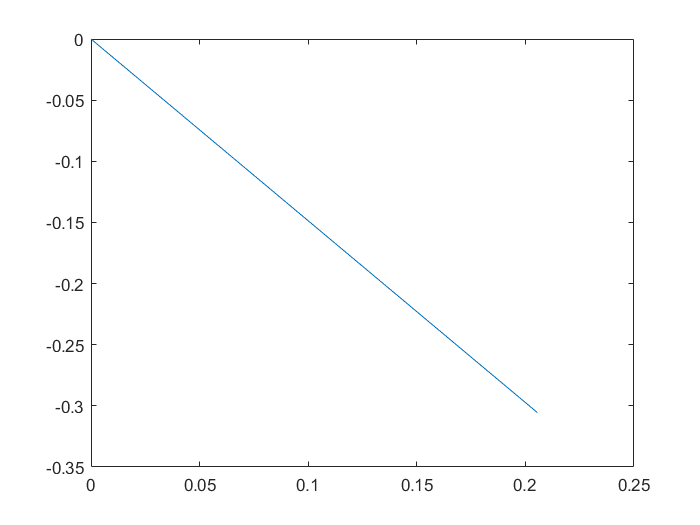

plot_resultant(qd_1)    % SE

qd_2 = vpa(subs(zeta,[q1_dot q2_dot],[0.748 -0.11]),5)

$$qd\_2 = \left(\begin{array}{c} -0.33\\ 0.33\\ 0\\ 0\\ 0\\ 0.748 \end{array}\right)$$

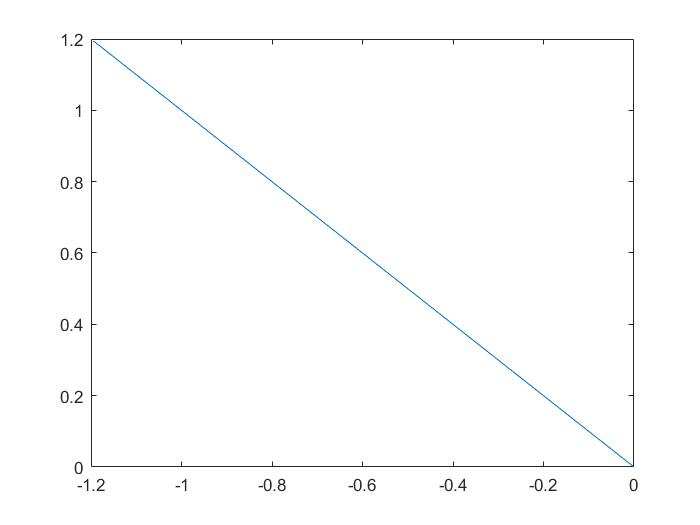

plot_resultant(qd_2)    % NW

qd_3 = vpa(subs(zeta,[q1_dot q2_dot],[-0.64 -0.2]),5)

$$qd\_3 = \left(\begin{array}{c} 0\\ -0.2\\ 0\\ 0\\ 0\\ -0.64 \end{array}\right)$$

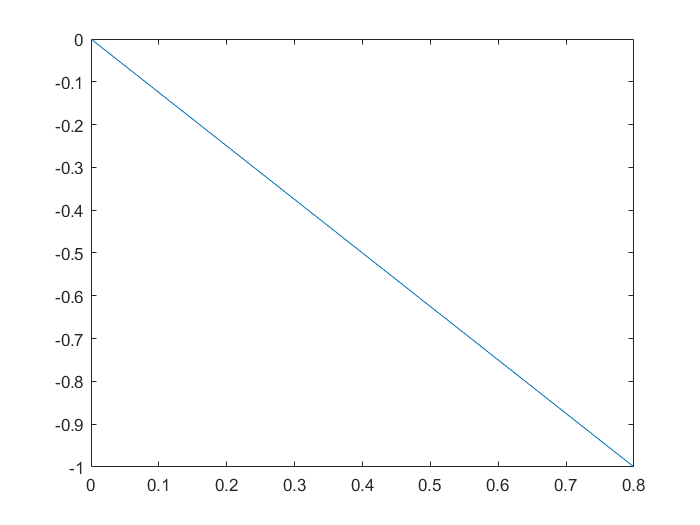

plot_resultant(qd_3)    % SE

qd_4 = vpa(subs(zeta,[q1_dot q2_dot],[0.14 0.2]),5)

$$qd\_4 = \left(\begin{array}{c} 0.15\\ 0\\ 0\\ 0\\ 0\\ 0.14 \end{array}\right)$$

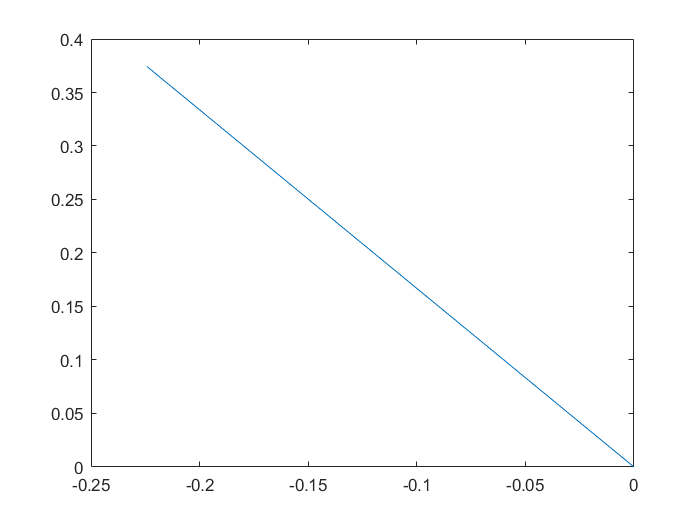

plot_resultant(qd_4)    % NW

qd_5 = vpa(subs(zeta,[q1_dot q2_dot],[0.8 0.25]),5)

$$qd\_5 = \left(\begin{array}{c} 0\\ 0.25\\ 0\\ 0\\ 0\\ 0.8 \end{array}\right)$$

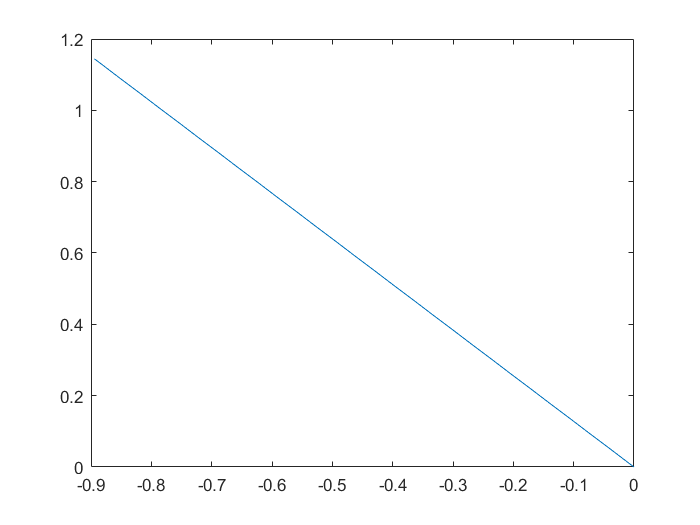

plot_resultant(qd_5)    % NW

% Q3.2
clear;

syms t_a t_b

T = [1 t_a t_a^2 t_a^3 t_a^4 t_a^5;
    0 1 2*t_a 3*t_a^2 4*t_a^3 5*t_a^4;
    0 0 2 6*t_a 12*t_a^2 20*t_a^3;
    1 t_b t_b^2 t_b^3 t_b^4 t_b^5;
    0 1 2*t_b 3*t_b^2 4*t_b^3 5*t_b^4;
    0 0 2 6*t_b 12*t_b^2 20*t_b^3]

$$T = \left(\begin{array}{cccccc} 1 & t_{a} & {t_{a}}^{2} & {t_{a}}^{3} & {t_{a}}^{4} & {t_{a}}^{5}\\ 0 & 1 & 2\,t_{a} & 3\,{t_{a}}^{2} & 4\,{t_{a}}^{3} & 5\,{t_{a}}^{4}\\ 0 & 0 & 2 & 6\,t_{a} & 12\,{t_{a}}^{2} & 20\,{t_{a}}^{3}\\ 1 & t_{b} & {t_{b}}^{2} & {t_{b}}^{3} & {t_{b}}^{4} & {t_{b}}^{5}\\ 0 & 1 & 2\,t_{b} & 3\,{t_{b}}^{2} & 4\,{t_{b}}^{3} & 5\,{t_{b}}^{4}\\ 0 & 0 & 2 & 6\,t_{b} & 12\,{t_{b}}^{2} & 20\,{t_{b}}^{3} \end{array}\right)$$

T = subs(T,[t_a t_b],[0 2])

$$T = \left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 2 & 0 & 0 & 0\\ 1 & 2 & 4 & 8 & 16 & 32\\ 0 & 1 & 4 & 12 & 32 & 80\\ 0 & 0 & 2 & 12 & 48 & 160 \end{array}\right)$$

q_a = pi/5;
q_d_a = -pi/10;
q_dd_a = 0;

q_b = pi/2;
q_d_b = 3*pi/20;
q_dd_b = 0;
c = inv(T)*[q_a; q_d_a; q_dd_a; q_b; q_d_b; q_dd_b]

$$c = \left(\begin{array}{c} \frac{\pi }{5}\\ -\frac{\pi }{10}\\ 0\\ \frac{3\,\pi }{8}\\ -\frac{\pi }{4}\\ \frac{3\,\pi }{64} \end{array}\right)$$

vpa(c,5)        % coefficients for quintic polynomial

$$ans = \left(\begin{array}{c} 0.62832\\ -0.31416\\ 0\\ 1.1781\\ -0.7854\\ 0.14726 \end{array}\right)$$

syms t
qdd = 2*c(3) + 6*c(4)*t + 12*c(5)*t^2 + 20*c(6)*t^3

$$qdd = \frac{15\,\pi \,t^{3}}{16}-3\,\pi \,t^{2}+\frac{9\,\pi \,t}{4}$$

vpa(subs(qdd,t,1),5)        % acceleration at t=1

$$ans = 0.58905$$

## Problem 4

% Q4.1
or = 250;
oc = 250;
lambda = 8;     % mm
lambda = lambda/1000;   % m
alpha_x = 79.2;     % pix / mm
alpha_y = 120.5;    % pix / mm
alpha_x = alpha_x*1000;    % pix / m
alpha_y = alpha_y*1000;    % pix / m

p1 = [476;222];
p2 = [295;222];
p3 = [295;99];
p4 = [476;99];
p5 = [448;226];
p6 = [290;226];
p7 = [290;117];
p8 = [210;117];
p9 = [147;117];

% depth of p5, p6, p7, p8, p9 : 8m

% pixels -> {world}
zc = 8;    % m
p5_xc = (p5(1)-or)*zc/alpha_x;
p5_yc = (p5(2)-oc)*zc/alpha_y;
p5_c = [p5_xc; p5_yc];   % in m

p6_xc = (p6(1)-or)*zc/alpha_x;
p6_yc = (p6(2)-oc)*zc/alpha_y;
p6_c = [p6_xc; p6_yc];

p7_xc = (p7(1)-or)*zc/alpha_x;
p7_yc = (p7(2)-oc)*zc/alpha_y;
p7_c = [p7_xc; p7_yc];

p8_xc = (p8(1)-or)*zc/alpha_x;
p8_yc = (p8(2)-oc)*zc/alpha_y;
p8_c = [p8_xc; p8_yc];

p9_xc = (p9(1)-or)*zc/alpha_x;
p9_yc = (p9(2)-oc)*zc/alpha_y;
p9_c = [p9_xc; p9_yc];

door_width_c = norm(p8_c-p9_c)

door_width_c = 0.0064

couch_height_c = norm(p7_c-p6_c)

couch_height_c = 0.0072

couch_length_c = norm(p6_c-p5_c)

couch_length_c = 0.0160

length = couch_length_c/door_width_c*0.80   % m

length = 2.0063

height = couch_height_c/door_width_c*0.80    % m

height = 0.9097

% Since door_width in {camera} < couch_height in {camera}, 
% the couch cannot pass through the door.

% incomplete
P7_cx = (290-250)/alpha_x

P7_cx = 5.0505e-04

P7_wx = P7_cy/lambda*8

P7_wx = -1.1037

P3_cx = (295-250)/alpha_x

P3_cx = 5.6818e-04

P3_wx = P7_wx;
P3_wz = P3_wx*lambda/P3_cx

P3_wz = -15.5406

% Q4.2
P1H = [263;485];
P1F = [263;154];
P2H = [234;401];
P2F = [234;190];

z1 = 5;
P1_Hc = (P1H(2)-oc)/alpha_y;
P1_Fc = (P1F(2)-oc)/alpha_y;
P1_height_c = P1_Hc - P1_Fc     % in {camera}, m

P1_height_c = 0.0027

P1_height = z1/lambda*P1_height_c

P1_height = 1.7168

z2 = 8;     % m
P2_Hc = (P2H(2)-oc)/alpha_y;
P2_Fc = (P2F(2)-oc)/alpha_y;
P2_height_c = P2_Hc - P2_Fc     % in {camera}, m

P2_height_c = 0.0018

P2_height = z2/lambda*P2_height_c

P2_height = 1.7510

% Q4.3
% c coordinate is increasing, so the camera is moving down
% thus, y_speed is positive
d = 1.5;
pixel_diff = (314-121)/alpha_y;
y_speed = d/lambda*pixel_diff   % m travelled in 1.3s

y_speed = 0.3003

time = 1.3;
y_speed = y_speed/time  % final answer

y_speed = 0.2310

## Problem 5

function plot_resultant(vect)
    % for Q3.1
    vx = [vect(1);0];
    vy = [0; vect(2)];
    wz_magnitude = abs(vect(6));
    wz_direction = sign(vect(6));
    wz = wz_direction*[-sqrt(wz_magnitude);sqrt(wz_magnitude)];
    resultant = vx+vy+wz;
    plot([0 resultant(1)],[0 resultant(2)])
end